## Add stuff to path

datecode = '20170206';

if(ispc)
    homeFolder = 'C:\Users\rhc307\';
else
    homeFolder = '/home/raeed/';
end
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'BumpCurl' filesep 'lib' filesep])
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'lib']))
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'BumpCurl' filesep 'Han' filesep datecode filesep])

clear homeFolder


## Load CDS files

% set up input structs
root_folder = 'C:\Users\rhc307\Projects\limblab\data-raeed\BumpCurl\Han\20170206\';
fname_prefix = ['Han_' datecode '_CObumpcurl'];

% input_struct.lab=6;
% input_struct.ranBy='ranByRaeed';
% input_struct.monkey='monkeyHan';
% input_struct.task='taskCObump';
% input_struct.array='arrayLeftS1Area2';
% input_struct.folder=[root_folder 'preCDS'];
% input_struct.mapfile='mapFileC:\Users\rhc307\Projects\limblab\data-raeed\ForceKin\OutOutReach\Han\mapfile\left_S1\SN 6251-001459.cmp';
% 
% base_input = input_struct;
% adapt_input = input_struct;
% wash_input = input_struct;
% extra_base_input = input_struct;
% extra_adapt_input = input_struct;
% extra_wash_input = input_struct;
% 
% base_input.fname= [fname_prefix '_baseline_area2EMG_001'];
% adapt_input.fname=[fname_prefix '_adaptation_area2EMG_003'];
% wash_input.fname= [fname_prefix '_washout_area2EMG_004'];
% 
% extra_base_input.fname= [fname_prefix '_baseline_EMGextra_001'];
% extra_adapt_input.fname=[fname_prefix '_adaptation_EMGextra_003'];
% extra_wash_input.fname= [fname_prefix '_washout_EMGextra_004'];
% 
% base_input.save_folder =  [root_folder 'CDS\' fname_prefix '_baseline_001_area2EMG_CDS.mat'];
% adapt_input.save_folder = [root_folder 'CDS\' fname_prefix '_adaptation_area2EMG_CDS.mat'];
% wash_input.save_folder =  [root_folder 'CDS\' fname_prefix '_washout_area2EMG_CDS.mat'];
% 
% extra_base_input.save_folder =  [root_folder 'CDS\' fname_prefix '_baseline_001_EMGextra_CDS.mat'];
% extra_adapt_input.save_folder = [root_folder 'CDS\' fname_prefix '_adaptation_EMGextra_CDS.mat'];
% extra_wash_input.save_folder =  [root_folder 'CDS\' fname_prefix '_washout_EMGextra_CDS.mat'];
% 
% base_cds = loadsave_cds(base_input);
% adapt_cds = loadsave_cds(adapt_input);
% wash_cds = loadsave_cds(wash_input);
% 
% extra_base_cds = loadsave_cds(extra_base_input);
% extra_adapt_cds = loadsave_cds(extra_adapt_input);
% extra_wash_cds = loadsave_cds(extra_wash_input);

base_cds = load(['CDS\' fname_prefix '_baseline_area2EMG_CDS.mat'],'cds');
adapt_cds = load(['CDS\' fname_prefix '_adaptation_area2EMG_CDS.mat'],'cds');
wash_cds = load(['CDS\' fname_prefix '_washout_area2EMG_CDS.mat'],'cds');

extra_base_cds = load(['CDS\' fname_prefix '_baseline_EMGextra_CDS.mat'],'cds');
extra_adapt_cds = load(['CDS\' fname_prefix '_adaptation_EMGextra_CDS.mat'],'cds');
extra_wash_cds = load(['CDS\' fname_prefix '_washout_EMGextra_CDS.mat'],'cds');

base_cds = base_cds.cds;
adapt_cds = adapt_cds.cds;
wash_cds = wash_cds.cds;

extra_base_cds = extra_base_cds.cds;
extra_adapt_cds = extra_adapt_cds.cds;
extra_wash_cds = extra_wash_cds.cds;



You cannot set the read-only property 'emg' of commonDataStructure.

## Extract data from cds files

[base_data,base_table] = extract_bumpcurl_data(base_cds);

[adapt_data,adapt_table] = extract_bumpcurl_data(adapt_cds);

[wash_data,wash_table] = extract_bumpcurl_data(wash_cds);


[extra_base_data] = extract_extra_bumpcurl_data(extra_base_cds);

Error using experiment/addSession (line 22)
addSession expected either a cds object or a path to a cds object as input

Error in extract_extra_bumpcurl_data (line 23)
ex.addSession(cds);

[extra_adapt_data] = extract_extra_bumpcurl_data(extra_adapt_cds);
[extra_wash_data] = extract_extra_bumpcurl_data(extra_wash_cds);

clear *_input;
clear root_folder;
clear fname_prefix;


## Check trial tables

% check reward tables
% base_table = base_cds.trials(base_cds.trials.result=='R',:);
% adapt_table = adapt_cds.trials(adapt_cds.trials.result=='R',:);
% wash_table = wash_cds.trials(wash_cds.trials.result=='R',:);
% base_table = base_table(base_cds.trials.result=='R',:);
% adapt_table = adapt_table(adapt_cds.trials.result=='R',:);
% wash_table = wash_table(wash_cds.trials.result=='R',:);

% clear all trials with no center hold bump
base_table = base_table(base_table.ctrHoldBump==1 & ~isnan(base_table.bumpTime),:);
adapt_table = adapt_table(adapt_table.ctrHoldBump==1 & ~isnan(adapt_table.bumpTime),:);
wash_table = wash_table(wash_table.ctrHoldBump==1 & ~isnan(wash_table.bumpTime),:);


## Check if extra stuff is lined up with neural stuff

figure
subplot(311)
plot(base_data.t,base_data.KinectSyncPulse)
hold on
plot(extra_base_data.t,extra_base_data.Sync)
subplot(312)
plot(adapt_data.t,adapt_data.KinectSyncPulse)
hold on
plot(extra_adapt_data.t,extra_adapt_data.Sync)
subplot(313)
plot(wash_data.t,wash_data.KinectSyncPulse)
hold on
plot(extra_wash_data.t,extra_wash_data.Sync)


## Concatenate data tables

interp_extra_base = array2table(interp1(extra_base_data.t,extra_base_data{:,2:end},base_data.t),'VariableNames',extra_base_data.Properties.VariableNames(2:end));
interp_extra_adapt = array2table(interp1(extra_adapt_data.t,extra_adapt_data{:,2:end},adapt_data.t),'VariableNames',extra_adapt_data.Properties.VariableNames(2:end));
interp_extra_wash = array2table(interp1(extra_wash_data.t,extra_wash_data{:,2:end},wash_data.t),'VariableNames',extra_wash_data.Properties.VariableNames(2:end));

base_data = [base_data interp_extra_base];
adapt_data = [adapt_data interp_extra_adapt];
wash_data = [wash_data interp_extra_wash];

clear interp_*


## Process EMGs

## Try PCA on data

neurIDX = contains(base_data.Properties.VariableNames,'LeftS1Area2CH');
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,neurIDX}];
end

[coeff,scores,latent_eigs] = pca([base_bumps;adapt_bumps;wash_bumps]);
% [base_coeff,base_scores,base_scree] = pca([base_bumps]);

% project adapt and wash bumps into pc space
% center
% adapt_bumps_ctr = adapt_bumps - mean(adapt_bumps);
% wash_bumps_ctr = wash_bumps - mean(wash_bumps);
% 
% % project
% adapt_scores = adapt_bumps_ctr*base_coeff;
% wash_scores = wash_bumps_ctr*base_coeff;
% 


base_idx = (1:size(base_bumps,1))';
adapt_idx = (base_idx(end)+1:base_idx(end)+size(adapt_bumps,1))';
wash_idx = (adapt_idx(end)+1:adapt_idx(end)+size(wash_bumps,1))';

base_scores = scores(base_idx,:);
adapt_scores = scores(adapt_idx,:);
wash_scores = scores(wash_idx,:);

base_scree = var(base_scores);
adapt_scree = var(adapt_scores);
wash_scree = var(wash_scores);

figure
subplot(311)
bar(base_scree(1:20))
subplot(312)
bar(adapt_scree(1:20))
subplot(313)
bar(wash_scree(1:20))


## Look at PCs time traces

## Plot color bumps

num_bumps = 4;

bump_sep = 360/num_bumps;

colors = linspecer(num_bumps);
base_colors = colors(floor(base_table.bumpDir/bump_sep+1),:);
adapt_colors = colors(floor(adapt_table.bumpDir/bump_sep+1),:);
wash_colors = colors(floor(wash_table.bumpDir/bump_sep+1),:);

figure
S = linspace(1,200,size(base_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(base_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),'Color',base_colors(i,:))
%         plot(base_scores(idx,1),base_scores(idx,2),'o','Color',base_colors(i,:))
        hold on
        scatter3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),S(i),base_colors(i,:))
    end
    grid off
    axis square
end


figure
S = linspace(1,200,size(adapt_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(adapt_colors,1)
        
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),'Color',adapt_colors(i,:))
%         plot(adapt_scores(idx,1),adapt_scores(idx,2),'o','Color',adapt_colors(i,:))
        hold on
%         scatter(adapt_scores(idx,1),adapt_scores(idx,2),S(i),adapt_colors(i,:))
        scatter3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),S(i),adapt_colors(i,:))
        
    end
    grid off
    axis square
end

figure
S = linspace(1,200,size(wash_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(wash_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),'Color',wash_colors(i,:))
%         plot(wash_scores(idx,1),wash_scores(idx,2),'o','Color',wash_colors(i,:))
        hold on
%         scatter(wash_scores(idx,1),wash_scores(idx,2),S(i),wash_colors(i,:))
        scatter3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),S(i),wash_colors(i,:))
    end
    grid off
    axis square
end



## Try time spread PCA

% % neurIDX = contains(base_data.Properties.VariableNames,'LeftS1Area2CH');
% % % base_bumps = [];
% % % for trialCtr=1:height(base_table)
% % %     base_bumps = [base_bumps; reshape(base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% % % end
% % % 
% % % neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
% % % adapt_bumps = [];
% % % for trialCtr=1:height(adapt_table)
% % %     adapt_bumps = [adapt_bumps; reshape(adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% % % end
% % % 
% % % neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
% % % wash_bumps = [];
% % % for trialCtr=1:height(wash_table)
% % %     wash_bumps = [wash_bumps; reshape(wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,neurIDX},1,6*sum(neurIDX))];
% % % end
% % 
% % % Try picking out the time points
% % base_bumps = [];
% % for trialCtr=1:height(base_table)
% %     base_bumps = [base_bumps; reshape(base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.15,neurIDX},1,3*sum(neurIDX))];
% % end
% % 
% % neurIDX = contains(adapt_data.Properties.VariableNames,'LeftS1Area2CH');
% % adapt_bumps = [];
% % for trialCtr=1:height(adapt_table)
% %     adapt_bumps = [adapt_bumps; reshape(adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr)+0.05 & adapt_data.t<adapt_table.bumpTime(trialCtr)+0.20,neurIDX},1,3*sum(neurIDX))];
% % end
% % 
% % neurIDX = contains(wash_data.Properties.VariableNames,'LeftS1Area2CH');
% % wash_bumps = [];
% % for trialCtr=1:height(wash_table)
% %     wash_bumps = [wash_bumps; reshape(wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.15,neurIDX},1,3*sum(neurIDX))];
% % end
% % 
% % % [coeff,scores,latent_eigs] = pca([base_bumps;adapt_bumps;wash_bumps]);
% % [base_coeff,base_scores,base_scree] = pca(base_bumps);
% % % [~,adapt_scores,~] = pca(adapt_bumps);
% % % [~,wash_scores,~] = pca(wash_bumps);
% % % 
% % % project adapt and wash bumps into pc space
% % % center
% % adapt_bumps_ctr = adapt_bumps - mean(adapt_bumps);
% % wash_bumps_ctr = wash_bumps - mean(wash_bumps);
% % 
% % % project
% % adapt_scores = adapt_bumps_ctr*base_coeff;
% % wash_scores = wash_bumps_ctr*base_coeff;
% % 
% % adapt_scree = var(adapt_scores);
% % wash_scree = var(wash_scores);
% % 
% % % base_idx = (1:size(base_bumps,1))';
% % % adapt_idx = (base_idx(end)+1:base_idx(end)+size(adapt_bumps,1))';
% % % wash_idx = (adapt_idx(end)+1:adapt_idx(end)+size(wash_bumps,1))';
% % % 
% % % base_scores = scores(base_idx,:);
% % % adapt_scores = scores(adapt_idx,:);
% % % wash_scores = scores(wash_idx,:);
% % 
% % figure
% % subplot(311)
% % bar(base_scree(1:20))
% % subplot(312)
% % bar(adapt_scree(1:20))
% % subplot(313)
% % bar(wash_scree(1:20))
% % 

## plot colors

% % num_bumps = 4;
% % 
% % bump_sep = 360/num_bumps;
% % 
% % colors = linspecer(num_bumps);
% % base_colors = colors(floor(base_table.bumpDir/bump_sep+1),:);
% % adapt_colors = colors(floor(adapt_table.bumpDir/bump_sep+1),:);
% % wash_colors = colors(floor(wash_table.bumpDir/bump_sep+1),:);
% % 
% % figure
% % S = linspace(1,40,size(base_scores,1));
% % scatter3(base_scores(:,1),base_scores(:,2),base_scores(:,3),S,base_colors)
% % % scatter(base_scores(:,1),base_scores(:,2),S,base_colors)
% % grid off
% % % axis equal
% % figure
% % S = linspace(1,40,size(adapt_scores,1));
% % scatter3(adapt_scores(:,1),adapt_scores(:,2),adapt_scores(:,3),S,adapt_colors)
% % % scatter(adapt_scores(:,1),adapt_scores(:,2),S,adapt_colors)
% % grid off
% % % axis equal
% % figure
% % subplot(221)
% % scatter(adapt_scores(1:111,1),adapt_scores(1:111,2),30,adapt_colors(1:111,:))
% % title 'split 1'
% % subplot(222)
% % scatter(adapt_scores(112:222,1),adapt_scores(112:222,2),30,adapt_colors(112:222,:))
% % title 'split 2'
% % subplot(223)
% % scatter(adapt_scores(223:333,1),adapt_scores(223:333,2),30,adapt_colors(223:333,:))
% % title 'split 3'
% % subplot(224)
% % scatter(adapt_scores(334:444,1),adapt_scores(334:444,2),30,adapt_colors(334:444,:))
% % title 'split 4'
% % 
% % figure
% % S = linspace(1,40,size(wash_scores,1));
% % scatter3(wash_scores(:,1),wash_scores(:,2),wash_scores(:,3),S,wash_colors)
% % % scatter(wash_scores(:,1),wash_scores(:,2),S,wash_colors)
% % grid off
% % % axis equal
% % 
% % figure
% % subplot(221)
% % scatter(wash_scores(1:111,1),wash_scores(1:111,2),30,wash_colors(1:111,:))
% % title 'split 1'
% % subplot(222)
% % scatter(wash_scores(112:222,1),wash_scores(112:222,2),30,wash_colors(112:222,:))
% % title 'split 2'
% % subplot(223)
% % scatter(wash_scores(223:333,1),wash_scores(223:333,2),30,wash_colors(223:333,:))
% % title 'split 3'
% % subplot(224)
% % scatter(wash_scores(334:444,1),wash_scores(334:444,2),30,wash_colors(334:444,:))
% % title 'split 4'



## Try mahalanobis distance on time-spread PCA

base_clusters = cell(8,1);
for i = 1:8
    base_clusters{i} = base_scores(base_table.bumpDir/45+1==i,1:12);
end

adapt_clusters = cell(8,1);
for i = 1:8
    adapt_clusters{i} = adapt_scores(adapt_table.bumpDir/45+1==i,1:12);
end

wash_clusters = cell(8,1);
for i = 1:8
    wash_clusters{i} = wash_scores(wash_table.bumpDir/45+1==i,1:12);
end

min_mahal = inf;
max_mahal = 0;

base_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(base_clusters{j},1)
        for i = 1:8
            if i==j
                base_mahal{j}(trialCtr,i) = mahal(base_clusters{j}(trialCtr,1:12),base_clusters{i}([1:trialCtr-1 trialCtr+1:end],:));
            else
                base_mahal{j}(trialCtr,i) = mahal(base_clusters{j}(trialCtr,1:12),base_clusters{i});
            end
            if min_mahal>base_mahal{j}(trialCtr,i)
                min_mahal = base_mahal{j}(trialCtr,i);
            end
            if max_mahal<base_mahal{j}(trialCtr,i)
                max_mahal = base_mahal{j}(trialCtr,i);
            end
        end
    end
end

adapt_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(adapt_clusters{j},1)
        for i = 1:8
            adapt_mahal{j}(trialCtr,i) = mahal(adapt_clusters{j}(trialCtr,1:12),base_clusters{i});
        end
        if min_mahal>adapt_mahal{j}(trialCtr,i)
            min_mahal = adapt_mahal{j}(trialCtr,i);
        end
        if max_mahal<adapt_mahal{j}(trialCtr,i)
            max_mahal = adapt_mahal{j}(trialCtr,i);
        end
    end
end
wash_mahal = cell(8,1);
for j = 1:8
    for trialCtr = 1:size(wash_clusters{j},1)
        for i = 1:8
            wash_mahal{j}(trialCtr,i) = mahal(wash_clusters{j}(trialCtr,1:12),base_clusters{i});
        end
        if min_mahal>wash_mahal{j}(trialCtr,i)
            min_mahal = wash_mahal{j}(trialCtr,i);
        end
        if max_mahal<wash_mahal{j}(trialCtr,i)
            max_mahal = wash_mahal{j}(trialCtr,i);
        end
    end
end

figure
for i = 1:8
    subplot(8,3,3*(i-1)+1)
    imagesc(1./base_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
    subplot(8,3,3*(i-1)+2)
    imagesc(1./adapt_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
    subplot(8,3,3*(i-1)+3)
    imagesc(1./wash_mahal{i}',[1/max_mahal 1/min_mahal])
    colorbar
end



## Calculate principle angles

[base_coeff,base_scores,base_scree] = pca(base_bumps);
[adapt_coeff,adapt_scores,~] = pca(adapt_bumps);
[wash_coeff,wash_scores,~] = pca(wash_bumps);

adapt_base_angles = principle_angles(base_coeff(:,1:12),wash_coeff(:,1:12));

figure
plot(adapt_base_angles*180/pi)


## Look at behavior

% kinIDX = [4 5];
kinIDX = [6 7];
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,kinIDX}];
end

num_bumps = 4;

bump_sep = 360/num_bumps;

colors = linspecer(num_bumps);
base_colors = colors(floor(base_table.bumpDir/bump_sep+1),:);
adapt_colors = colors(floor(adapt_table.bumpDir/bump_sep+1),:);
wash_colors = colors(floor(wash_table.bumpDir/bump_sep+1),:);

figure
S = linspace(1,40,size(base_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(base_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),'Color',base_colors(i,:))
%         plot(base_scores(idx,1),base_scores(idx,2),'o','Color',base_colors(i,:))
        hold on
        scatter(base_bumps(idx,1),base_bumps(idx,2),S(i),base_colors(i,:))
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end


figure
S = linspace(1,40,size(adapt_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = size(adapt_colors,1)-150:size(adapt_colors,1)
        
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),'Color',adapt_colors(i,:))
%         plot(adapt_scores(idx,1),adapt_scores(idx,2),'o','Color',adapt_colors(i,:))
        hold on
        scatter(adapt_bumps(idx,1),adapt_bumps(idx,2),S(i),adapt_colors(i,:))
%         scatter3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),S(i),adapt_colors(i,:))
        
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end

figure
S = linspace(1,40,size(wash_bumps,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(wash_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),'Color',wash_colors(i,:))
%         plot(wash_scores(idx,1),wash_scores(idx,2),'o','Color',wash_colors(i,:))
        hold on
        scatter(wash_bumps(idx,1),wash_bumps(idx,2),S(i),wash_colors(i,:))
        
    end
    grid off
    axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end


## Look at EMG

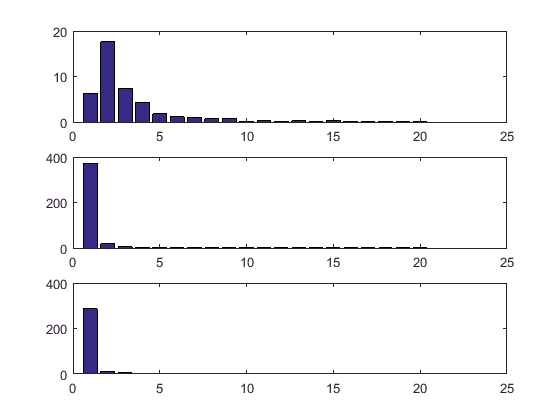

EMGIDX = contains(base_data.Properties.VariableNames,'EMG');
base_bumps = [];
for trialCtr=1:height(base_table)
    base_bumps = [base_bumps; base_data{base_data.t>=base_table.bumpTime(trialCtr) & base_data.t<=base_table.bumpTime(trialCtr)+0.3,EMGIDX}];
end

adapt_bumps = [];
for trialCtr=1:height(adapt_table)
    adapt_bumps = [adapt_bumps; adapt_data{adapt_data.t>=adapt_table.bumpTime(trialCtr) & adapt_data.t<=adapt_table.bumpTime(trialCtr)+0.3,EMGIDX}];
end

wash_bumps = [];
for trialCtr=1:height(wash_table)
    wash_bumps = [wash_bumps; wash_data{wash_data.t>=wash_table.bumpTime(trialCtr) & wash_data.t<=wash_table.bumpTime(trialCtr)+0.3,EMGIDX}];
end

[coeff,scores,latent_eigs] = pca([base_bumps;adapt_bumps;wash_bumps]);
% [base_coeff,base_scores,base_scree] = pca([base_bumps]);

% project adapt and wash bumps into pc space
% center
% adapt_bumps_ctr = adapt_bumps - mean(adapt_bumps);
% wash_bumps_ctr = wash_bumps - mean(wash_bumps);
% 
% % project
% adapt_scores = adapt_bumps_ctr*base_coeff;
% wash_scores = wash_bumps_ctr*base_coeff;
% 

% do pca
base_idx = (1:size(base_bumps,1))';
adapt_idx = (base_idx(end)+1:base_idx(end)+size(adapt_bumps,1))';
wash_idx = (adapt_idx(end)+1:adapt_idx(end)+size(wash_bumps,1))';

base_scores = scores(base_idx,:);
adapt_scores = scores(adapt_idx,:);
wash_scores = scores(wash_idx,:);

base_scree = var(base_scores);
adapt_scree = var(adapt_scores);
wash_scree = var(wash_scores);

figure
subplot(311)
bar(base_scree(1:20))
subplot(312)
bar(adapt_scree(1:20))
subplot(313)
bar(wash_scree(1:20))

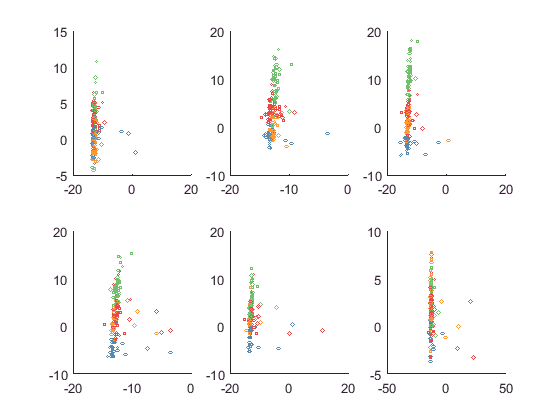


% plot bumps
num_bumps = 4;

bump_sep = 360/num_bumps;

colors = linspecer(num_bumps);
base_colors = colors(floor(base_table.bumpDir/(pi/2)+1),:);
adapt_colors = colors(floor(adapt_table.bumpDir/bump_sep+1),:);
wash_colors = colors(floor(wash_table.bumpDir/bump_sep+1),:);

figure
S = linspace(1,40,size(base_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(base_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(base_scores(idx,1),base_scores(idx,2),base_scores(idx,3),'Color',base_colors(i,:))
%         plot(base_scores(idx,1),base_scores(idx,2),'o','Color',base_colors(i,:))
        hold on
        scatter(base_scores(idx,1),base_scores(idx,2),S(i),base_colors(i,:))
    end
    grid off
%     axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end

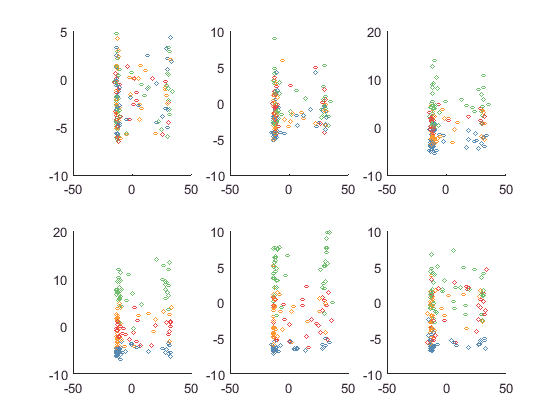



figure
S = linspace(1,40,size(adapt_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = size(adapt_colors,1)-150:size(adapt_colors,1)
        
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),'Color',adapt_colors(i,:))
%         plot(adapt_scores(idx,1),adapt_scores(idx,2),'o','Color',adapt_colors(i,:))
        hold on
        scatter(adapt_scores(idx,1),adapt_scores(idx,2),S(i),adapt_colors(i,:))
%         scatter3(adapt_scores(idx,1),adapt_scores(idx,2),adapt_scores(idx,3),S(i),adapt_colors(i,:))
        
    end
    grid off
%     axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end

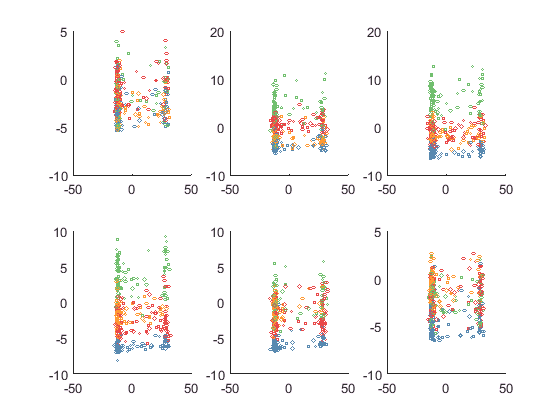


figure
S = linspace(1,40,size(wash_scores,1));
for j = 1:6
    subplot(2,3,j)
    for i = 1:size(wash_colors,1)
%         idx = (i-1)*6+1:i*6;
%         idx = i*6-3;
        idx = (i-1)*6+j;
%         plot3(wash_scores(idx,1),wash_scores(idx,2),wash_scores(idx,3),'Color',wash_colors(i,:))
%         plot(wash_scores(idx,1),wash_scores(idx,2),'o','Color',wash_colors(i,:))
        hold on
        scatter(wash_scores(idx,1),wash_scores(idx,2),S(i),wash_colors(i,:))
        
    end
    grid off
%     axis([-30 30 -30 30])
%     axis([-5 5 -40 -30])
end